# Metody optymalizacji - ćwiczenie 3

# Zadanie 1

### Nina Łabęcka 311339 grupa czwartek 14:15

### Dominika Pacek 311378 grupa czwartek 18:15

clc
clear
cvx_clear

Wczytanie danych

dane = load("zadanie1\Data01.mat")

dane = struct with fields:
    t: [1001×1 double]
    y: [1001×1 double]


y = dane.y;
n = length(y);

Rozwiązanie (3)

q = 1.5

q = 1.5000


cvx_begin quiet
    variable v(n)
    variable Dv(n)

    minimize(pow_pos(norm(y - v, 2), 2))

    for i = 1:n-1
        Dv(i) == v(i+1) - v(i);
    end
    subject to
        norm(Dv, 1) <= q;

cvx_end

Rozwiązanie (4) - LASSO

tau = 1.8

tau = 1.8000


cvx_begin quiet
    variable v4(n)
    variable Dv(n)

    minimize(pow_pos(norm(y - v4, 2), 2) + tau * norm(Dv, 1))

    for i = 1:n-1
        Dv(i) == v4(i+1) - v4(i);
    end
cvx_end

Rysowanie wykresu

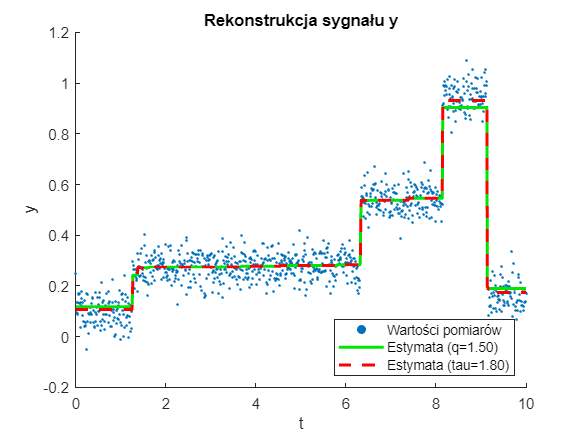

fig = figure;
    scatter(dane.t, dane.y, 3, 'filled', 'DisplayName', 'Wartości pomiarów');
    hold on;
    plot(dane.t, v, 'LineWidth', 2, 'Color', [0, 0.9, 0], ...
        'DisplayName', sprintf('Estymata (q=%.2f)', q))
    plot(dane.t, v4, 'LineWidth', 2, 'LineStyle', '--', 'Color', 'red', ...
        'DisplayName', sprintf('Estymata (tau=%.2f)', tau))

    xlabel('t');
    ylabel('y');
    legend('Location', 'southeast');
    title('Rekonstrukcja sygnału y');